# Sessió 11

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

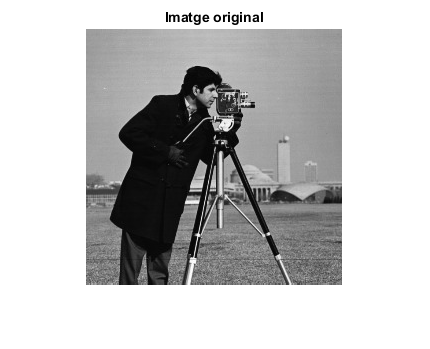

im= imread('cameraman.jpg');
imshow(im), title('Imatge original')

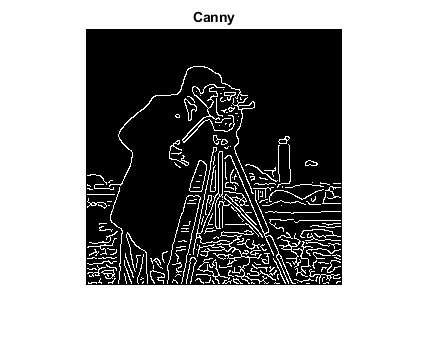

bw=edge(im,'canny');
figure,imshow(bw), title('Canny')

## Taula de Hough

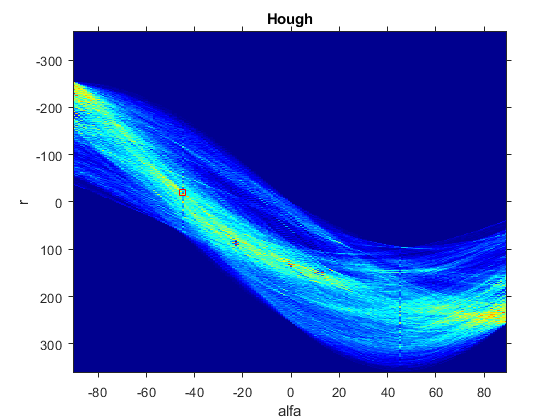

%TAULA DE HOUGH
[H,alfa,r] = hough(bw);
figure, imshow(mat2gray(H),'XData',alfa,'Ydata',r,'InitialMagnification','fit')
xlabel('alfa')
ylabel('r')
axis on
axis normal
colormap('jet')
title('Hough')
[fila col] = find(H==max(max(H)));
x = alfa(col);
y = r(fila);
hold on 
plot(x,y,'s','color','red')
hold off

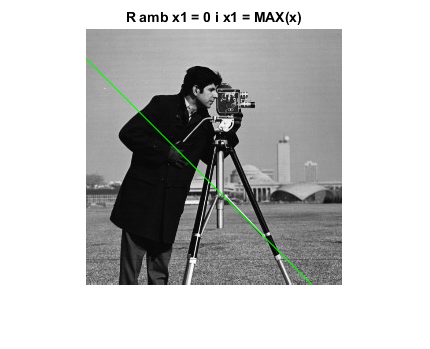

a = x*pi/180;
r=y;
[MAXY MAXX]=size(im);
x1 = 0;
y1 = r/sin(a);
x2 = MAXX;
y2 = (r-MAXX*cos(a))/(sin(a));
imshow(im),title('R amb x1 = 0 i x1 = MAX(x)')
hold on
line([x1, x2],[y1,y2],'color','g');

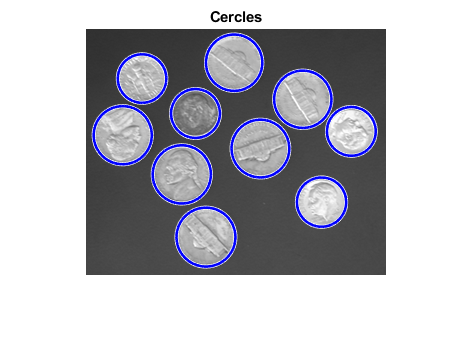

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


im=imread('coins.png');
figure, imshow(im)
[c r m] = imfindcircles(im,[15 30]);
viscircles(c,r,'EdgeColor','b'),title('Cercles');

## Taula de Harris

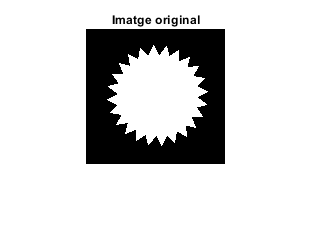

im = imread('gear.tif');
figure,imshow(im), title('Imatge original');

im = double(im);
k = 0.04;
th = 0.42;
h = ones(5);
[rows cols] = size(h);
h = h./(rows * cols);

#### Opció 1: Basic convolutions

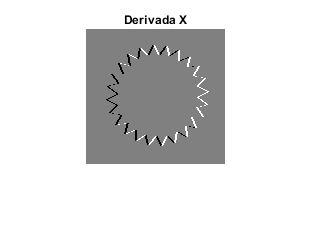

derivada = [-1 0 1];
iX=imfilter(im,derivada,'conv');
iY = imfilter(im,derivada','conv');
imshow(iX,[]), title('Derivada X')

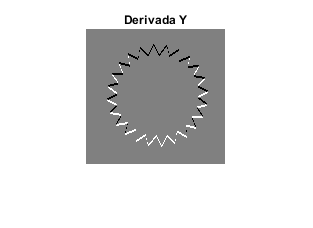

imshow(iY,[]), title('Derivada Y')

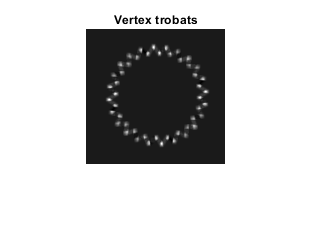

R = (imfilter(iX.^2,h,'conv').*imfilter(iY.^2,h,'conv')) - imfilter(iX.*iY,h,'conv').^2-k.*(imfilter(iX.^2,h,'conv')+imfilter(iY.^2,h,'conv')).^2;
representacioR = mat2gray(R);
figure,imshow(representacioR), title('Vertex trobats')

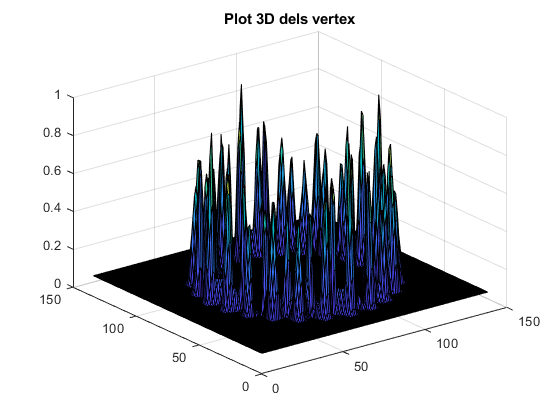

figure, surf(representacioR), title('Plot 3D dels vertex')

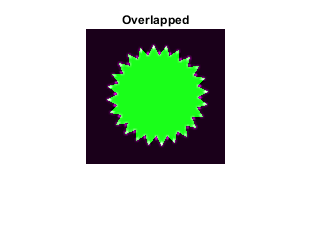

overlapped = imfuse(im,representacioR);
figure,imshow(overlapped), title('Overlapped')

#### Opció 2: threshold

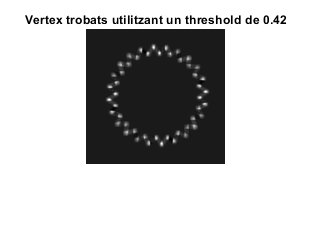

R = R(R>th);
figure,imshow(representacioR), title('Vertex trobats utilitzant un threshold de 0.42')

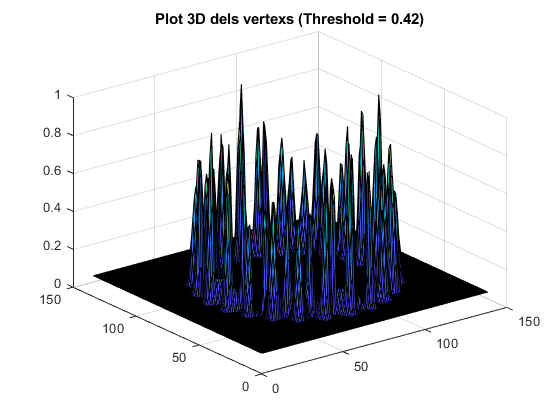

figure, surf(representacioR), title('Plot 3D dels vertexs (Threshold = 0.42)')

overlapped = imfuse(im,representacioR);
figure,imshow(overlapped), title('Overlapped')

#### Opció 3: Sobel

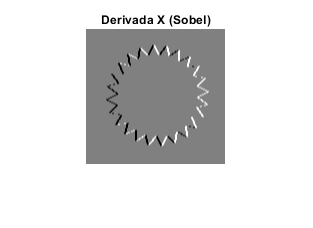

sobel = [-1 0 1;
        -2 0 2;
        -1 0 1];

iX=imfilter(im,sobel,'conv');
iY = imfilter(im,sobel','conv');
imshow(iX,[]), title('Derivada X (Sobel)')

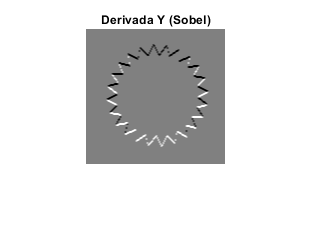

imshow(iY,[]), title('Derivada Y (Sobel)')

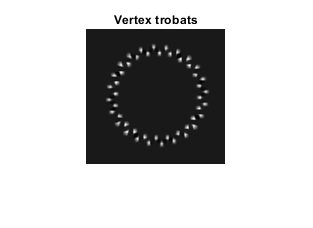

R = (imfilter(iX.^2,h,'conv').*imfilter(iY.^2,h,'conv')) - imfilter(iX.*iY,h,'conv').^2-k.*(imfilter(iX.^2,h,'conv')+imfilter(iY.^2,h,'conv')).^2;
representacioR = mat2gray(R);
figure,imshow(representacioR), title('Vertex trobats')

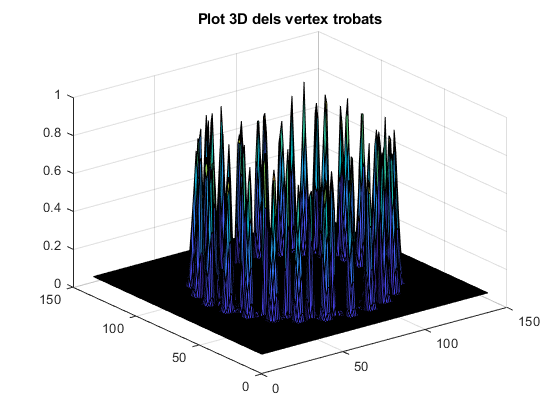

figure, surf(representacioR), title('Plot 3D dels vertex trobats')

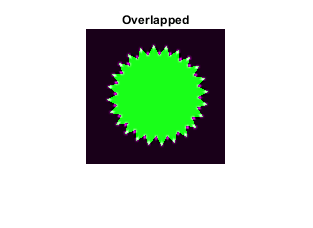

overlapped = imfuse(im,representacioR);
figure,imshow(overlapped), title('Overlapped')

#### Opció 4:  Supressió de no màxims utilizant Sobel (el que millors resultats dóna)

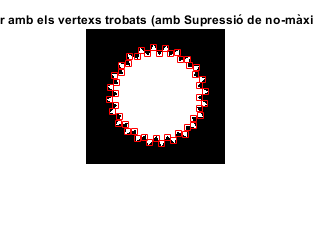

% Continuació de l'Opció 3
ee = strel('cube',3);
dilatada = imdilate(R,ee);
R(dilatada>R) = 0;
RL = (R > 0);
figure,imshow(im), title('Gear amb els vertexs trobats (amb Supressió de no-màxims)')


[ys xs] = find(RL);
hold on 
plot(xs,ys,'s','color','red')

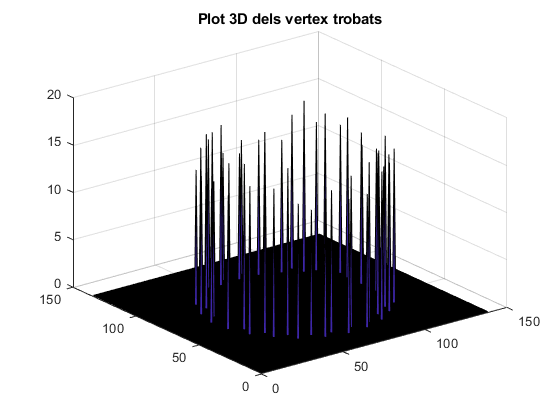


figure, surf(R), title('Plot 3D dels vertex trobats')

overlapped = imfuse(im,representacioR);
figure,imshow(overlapped), title('Overlapped')